app = actxserver('STK11.application');
root = app.Personality2; 

fprintf('正在重置 STK 场景，以确保环境干净...\n');

正在重置 STK 场景，以确保环境干净...


try
    root.CloseScenario(); % 强行关闭任何已打开的场景
catch ME
    % 如果没有打开的场景，CloseScenario 会报错，忽略这个错误
    fprintf('信息：没有需要关闭的旧场景。\n');
end

StartTime  =  '6 Jan 2025 00:00:00.000';
StopTime =  '7 Jan 2025 00:00:00.000';
scenario = root.Children.New('eScenario','MATLAB_PredatorMission');
scenario.SetTimePeriod(StartTime,StopTime);
scenario.StartTime = StartTime;
scenario.StopTime = StopTime;

try
        root.ExecuteCommand('Animate * Reset');
        disp('动画已复位成功');
    catch ME
        disp('动画复位失败:');
        disp(ME.message);
end

动画已复位成功


P = 10;
 N = 15;
%P =3
%N = 36
for i = 1:P
    
    %=============== 
    % 1. 设置“种子卫星”参数
    %=============== 
    % 为了区分不同循环生成的卫星，给种子卫星起一个带下标的名字
    seedSatelliteName = sprintf('QF_%d', i);
	
    % 轨道与初始状态参数
    params = struct();
    params.satelliteName = seedSatelliteName;
    params.perigeeAlt    = 1066;    % km
    params.apogeeAlt     = 1066;    % km
    params.inclination   = 89;      % 度
    params.argOfPerigee  = 0;       % 近地点幅角
    params.RAAN          = i*10.2;       % 升交点赤经(可按需在循环中改)
    params.Anomaly       = i*4.5;       % 真近点角(或平近点角)

    %=============== 
    % 2. 创建种子卫星
    %=============== 
    satObj = module.sat();  % 您自定义的 sat 类
    satObj.createSatellite(root, scenario, params);

    %=============== 
    % 3. 定义并创建 Walker 星座
    %=============== 
    % 这里设置1个轨道面、每面30颗卫星，不分面间相位增量
    params_constellation = struct();
    params_constellation.seedSatelliteName       = seedSatelliteName; 
    params_constellation.numPlanes               = 1;    % 轨道平面数量
    params_constellation.numSatsPerPlane         = N;   % 每个平面的卫星数
    params_constellation.interPlanePhaseIncrement= 0;    % 平面间相位增量(此处为0)

    satObj.createWalkerConstellation_Delta(root, params_constellation);

    %=============== 
    % 4. 卸载种子卫星
    %=============== 
    % 由于 Walker 星座已创建完，可以删除原先的种子卫星
    unloadCmd = sprintf('Unload / */Satellite/%s', seedSatelliteName);
    root.ExecuteCommand(unloadCmd);

end

执行的命令：
Walker */Satellite/QF_1 Type Delta  NumPlanes 1 NumSatsPerPlane 15 InterPlanePhaseIncrement 0 SetUniqueNames   Yes 
Walker 星座创建成功。
执行的命令：
Walker */Satellite/QF_2 Type Delta  NumPlanes 1 NumSatsPerPlane 15 InterPlanePhaseIncrement 0 SetUniqueNames   Yes 
Walker 星座创建成功。
执行的命令：
Walker */Satellite/QF_3 Type Delta  NumPlanes 1 NumSatsPerPlane 15 InterPlanePhaseIncrement 0 SetUniqueNames   Yes 
Walker 星座创建成功。
执行的命令：
Walker */Satellite/QF_4 Type Delta  NumPlanes 1 NumSatsPerPlane 15 InterPlanePhaseIncrement 0 SetUniqueNames   Yes 
Walker 星座创建成功。
执行的命令：
Walker */Satellite/QF_5 Type Delta  NumPlanes 1 NumSatsPerPlane 15 InterPlanePhaseIncrement 0 SetUniqueNames   Yes 
Walker 星座创建成功。
执行的命令：
Walker */Satellite/QF_6 Type Delta  NumPlanes 1 NumSatsPerPlane 15 InterPlanePhaseIncrement 0 SetUniqueNames   Yes 
Walker 星座创建成功。
执行的命令：
Walker */Satellite/QF_7 Type Delta  NumPlanes 1 NumSatsPerPlane 15 InterPlanePhaseIncrement 0 SetUniqueNames   Yes 
Walker 星座创建成功。
执行的命令：
Walker */Satellite/QF_8 Typ

satName1 = 'QF_1101'; % 替换为您想查询的第一颗卫星
satName2 = 'QF_2101'; % 替换为您想查询的第二颗卫星
timestep = 60;      % 采样时间步长（秒）

% 实例化 paperfunction 模块
paperFunc = module.paperfunction();

% 调用函数获取距离
% 该函数返回 UTC 时间的 datetime 向量 (t) 和 距离 (mag) 向量
disp(['正在计算 ', satName1, ' 与 ', satName2, ' 之间的距离...']);

正在计算 QF_1101 与 QF_2101 之间的距离...


计算完成。


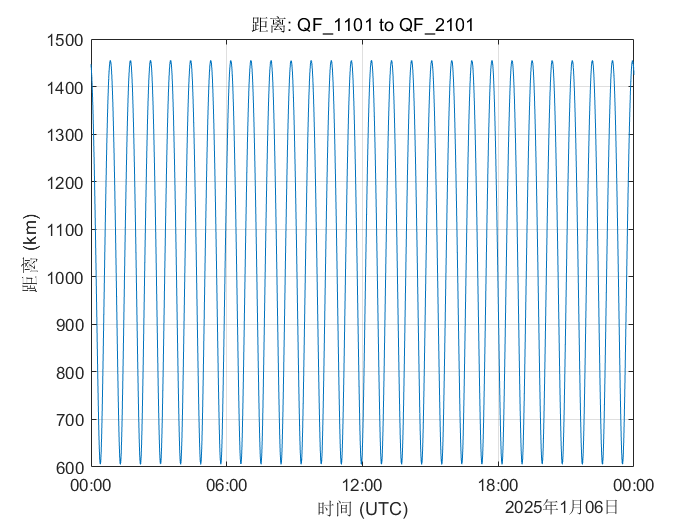

try
    [time_vec, distance_km] = paperFunc.ab_vector_range(root, satName1, satName2, timestep);
    
    disp('计算完成。');

    % 6. (可选) 绘制距离变化图
    % ==========================
    figure;
    plot(time_vec, distance_km);
    title(['距离: ', satName1, ' to ', satName2], 'Interpreter', 'none');
    xlabel('时间 (UTC)');
    ylabel('距离 (km)'); % 幅值单位通常是 km
    grid on;
    
    % 7. (可选) 保存数据到文件
    % ==========================
    % 
    % % 定义保存路径
    % save_path = 'C:\temp\distance_output.txt'; % 请修改为您希望的路径
    % 
    % % 检查目录是否存在
    % save_dir = fileparts(save_path);
    % if ~exist(save_dir, 'dir')
    %     mkdir(save_dir);
    % end
    % 
    % % 创建表格并写入文件
    % data_table = table(time_vec, distance_km, 'VariableNames', {'Time', 'Range_km'});
    % writetable(data_table, save_path, 'Delimiter', '\t');
    % disp(['数据已保存到文件：', save_path]);

catch ME
    disp(['计算距离时出错: ', ME.message]);
    disp('请确保卫星名称正确，并且 +module/paperfunction.m 已在 MATLAB 路径中。');
end

% ... 您的 STK 初始化和卫星创建代码 ...

sat = module.sat();
satellite_names =sat.getSatelliteNames(scenario);

卫星名称列表：
  1 至 12 列

    'QF_1101'    'QF_1102'    'QF_1103'    'QF_1104'    'QF_1105'    'QF_1106'    'QF_1107'    'QF_1108'    'QF_1109'    'QF_1110'    'QF_1111'    'QF_1112'

  13 至 24 列

    'QF_1113'    'QF_1114'    'QF_1115'    'QF_1116'    'QF_1117'    'QF_1118'    'QF_1119'    'QF_1120'    'QF_1121'    'QF_1122'    'QF_1123'    'QF_1124'

  25 至 36 列

    'QF_1125'    'QF_1126'    'QF_1127'    'QF_1128'    'QF_1129'    'QF_1130'    'QF_1131'    'QF_1132'    'QF_1133'    'QF_1134'    'QF_1135'    'QF_1136'

  37 至 48 列

    'QF_2101'    'QF_2102'    'QF_2103'    'QF_2104'    'QF_2105'    'QF_2106'    'QF_2107'    'QF_2108'    'QF_2109'    'QF_2110'    'QF_2111'    'QF_2112'

  49 至 60 列

    'QF_2113'    'QF_2114'    'QF_2115'    'QF_2116'    'QF_2117'    'QF_2118'    'QF_2119'    'QF_2120'    'QF_2121'    'QF_2122'    'QF_2123'    'QF_2124'

  61 至 72 列

    'QF_2125'    'QF_2126'    'QF_2127'    'QF_2128'    'QF_2129'    'QF_2130'    'QF_2131'    'QF_2132'    'QF_2133'    'QF_

sat.batchRenameSatellitesInSTK2(root,satellite_names) % 假设您使用了这个重命名函数

Executing command: Rename */Satellite/QF_1101 qf_1
Renamed satellite "QF_1101" to "qf_1" successfully.
Executing command: Rename */Satellite/QF_1102 qf_2
Renamed satellite "QF_1102" to "qf_2" successfully.
Executing command: Rename */Satellite/QF_1103 qf_3
Renamed satellite "QF_1103" to "qf_3" successfully.
Executing command: Rename */Satellite/QF_1104 qf_4
Renamed satellite "QF_1104" to "qf_4" successfully.
Executing command: Rename */Satellite/QF_1105 qf_5
Renamed satellite "QF_1105" to "qf_5" successfully.
Executing command: Rename */Satellite/QF_1106 qf_6
Renamed satellite "QF_1106" to "qf_6" successfully.
Executing command: Rename */Satellite/QF_1107 qf_7
Renamed satellite "QF_1107" to "qf_7" successfully.
Executing command: Rename */Satellite/QF_1108 qf_8
Renamed satellite "QF_1108" to "qf_8" successfully.
Executing command: Rename */Satellite/QF_1109 qf_9
Renamed satellite "QF_1109" to "qf_9" successfully.
Executing command: Rename */Satellite/QF_1110 qf_10
Renamed satellite "QF


% 现在设置特定卫星的颜色
module.setSatelliteColorRGB(root, 'qf_1', 255,0,0);  % 假设卫星被重命名为 qf_1

未定义函数或变量 'setSatelliteColor'。

setSatelliteColor(root, 'qf_2', 'green'); % 假设卫星被重命名为 qf_2